clear
simTimEnd=10;
samplingTime=0.01;

% Generating intial condition:
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x1=a+(b-a)*rand();
x2=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=1; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
    
        u1(index,:)=normrnd(0,1);
        u2(index,:)=normrnd(0,1); 
    %The contious time model: 
    x1dot=2*x2(index,1)+u1(index,:);
    x2dot=-0.8*x1(index,1)+2*x2(index,1)-10*x1(index,1)^2*x2(index,1)+u2(index,:);
    
   %Using forward euler to get the states value: 
    index=index+1; 
    x1(index,1)=x1dot*samplingTime+x1(index-1,1);
    x2(index,1)=x2dot*samplingTime+x2(index-1,1);
end
%Collecting x and u into one matrix
xAll=[x1';x2'];
uAll=[u1';u2'];

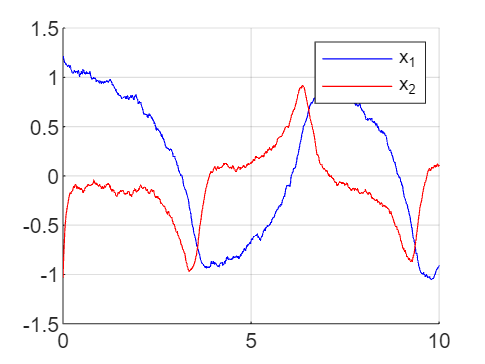

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 
clf
hold on 
plot(time,x1,'blue')
plot(time,x2,'red')
hold off 
grid
legend('x_1','x_2')

%Making the Hankel matrix, which will be based on 5050 points, and a delay
%of 50  (therefore from 1 to 5000 or from 50 to 5049!:

n=size(xAll,1);

d=50;
m=500; 
index=1;

for i=0:d
    H(index:index+n-1,:)=xAll(:,d-i+1:m-i);
    index=index+n;
end

%Takning the SVD of the Hankel matirx 
[U,S,V]=svd(H);


%Making the short version of the matrixs, based on trails 


    R=7; 
    Vr=V(:,1:R);
    Sr=S(1:R,1:R);
    Ur=U(:,1:R);

    cond(Sr)

ans = 71.3423

   
    %Making the concurrent and predict V based on the small V
    VrCon=Vr(1:end-1,:);
    VrPred=Vr(2:end,:);
    %Making transformation such that it is possible to transfer the matrix
    %to the V subspace
    Pup=(Ur*Sr);

    Pdown=pinv(Ur*Sr);

    %Making the Hankel matrix for the input series used for the
    %Measurement time series made eariliere. 
    index=1;

    d=50;
    m=m-1; 
    index=1;

    for i=0:d
        Hu(index:index+n-1,:)=uAll(:,d-i+1:m-i);
        index=index+n;
    end


    %Transforming the input series into the V space. 
    u=Pdown*Hu;
    
    %Making the G matrix
    G=[transpose(VrCon);u];

    
%Approximation the koopman operation A and B: 
temp=transpose(VrPred)*pinv(G);

%Splitting A and B up: 

A=temp(:,1:R); 
B=temp(:,R+1:end);
    

   
    




    %The times series of measurement and input
    % which is project to V, needs to have the same amout
    %of rows as H, as a delay of 50 was used and 2 states and 2 inputs
    % is present which
    %corresponds to 100 rows, therefore 99 present and the current sample
    %is used. The "model" was train on data from 0 to 549, therefore the 
    % time series starts at 451 to 550 and builds up to 1000

    %To only pickout the predited output instead of the entire sequences
    ny=2;
    Cc=[1, zeros(1,ny*(d+1)-1);0,1,zeros(1,ny*(d+1)-2)];

%Making one step prediction with input
for i=1:450
    %Taking out the 100 samples
      clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end

    clear Hru 
     index=1;
    for j=d+i:-1:i
        Hru(index:index+n-1,:)=uAll(:,500-d+j);
        index=index+n;
    end



    %Projecting to the V subspace: 
    Vk=Pdown*Hr; %Is v^T
    %Projecting inputs to V subspace:
    uk=Pdown*Hru;

    %Making prediction:
    PredictionV=A*Vk+B*uk;  %Prediction of V^T


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV; %PredictionV is already transpose and therefore no transpose here! 

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsave(:,i)=Cc*PreditionX; 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
end 

%Making one step prediction and forgotting the input
for i=1:500
    clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end

    clear Hru 
     index=1;
    for j=d+i:-1:i
        Hru(index:index+n-1,:)=uAll(:,500-d+j);
        index=index+n;
    end


    %Projecting to the V subspace: 
    Vk=Pdown*Hr; 
    %Projecting inputs to V subspace:
    uk=Pdown*Hru;

    %Making prediction:
   PredictionV=A*Vk; 


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    
    PredictionXsaveNoInput(:,i)=Cc*PreditionX;
    %PredictionXsaveNoInput(:,i)=transpose(PreditionX(end,:));
end 


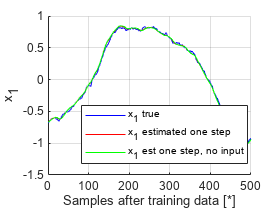

%Making plots of the estimation and the true simulated values for one step
%esitmation

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(x1(500:1000-1,1),'blue')
plot(PredictionXsave(1,:),'red')
plot(PredictionXsaveNoInput(1,:),'green')
hold off 
grid
legend('x_1 true','x_1 estimated one step',"x_1 est one step, no input",'location','best')
xlabel("Samples after training data [*]")
ylabel('x_1')
ax=gca;
exportgraphics(ax,"x1_HAVOK_with_input.pdf")

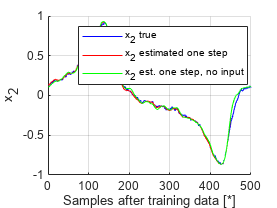



clf
hold on 
plot(x2(500:1000-1,1),'blue')
plot(PredictionXsave(2,:),'red')
plot(PredictionXsaveNoInput(2,:),'green')

hold off 
grid
legend('x_2 true','x_2 estimated one step',"x_2 est. one step, no input",'location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')


ax=gca;
exportgraphics(ax,"x2_HAVOK_with_input.pdf")

%Making multiple step prediction with input 

%Taking out the 100 samples
    i=1;
    clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end
for i=1:500
    %Taking out the 100 data inputs: 
    clear Hru 
     index=1;
    for j=d+i:-1:i
        Hru(index:index+n-1,:)=uAll(:,500-d+j);
        index=index+n;
    end

    %Projecting to the V subspace: 
    Vk=Pdown*Hr; %Is v^T
    %Projecting inputs to V subspace:
    uk=Pdown*Hru;

    %Making prediction:
    PredictionV=A*Vk+B*uk;  %Prediction of V^T


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV; %PredictionV is already transpose and therefore no transpose here! 

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsaveMulti(:,i)=Cc*PreditionX; 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
    Hr=[ Cc*PreditionX; Hr(1:end-n,:)];
end 

%Making multiple step prediction without input 
    i=1;
    clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end

for i=1:500

    %Projecting to the V subspace: 
    Vk=Pdown*Hr; %Is v^T

    %Making prediction:
    PredictionV=A*Vk;  %Prediction of V^T


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV; %PredictionV is already transpose and therefore no transpose here! 

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsaveMultiNoInput(:,i)=Cc*PreditionX; 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
    Hr=[Cc*PreditionX; Hr(1:end-n,1)];
end 

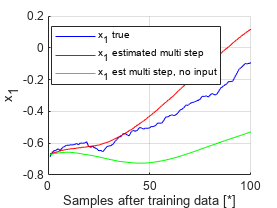

%Plotting the graphs

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(x1(500:1000-1,1),'blue')
plot(PredictionXsaveMulti(1,:),'red')
plot(PredictionXsaveMultiNoInput(1,:),'green')
hold off 
grid
legend('x_1 true','x_1 estimated multi step',"x_1 est multi step, no input",'location','best')
xlabel("Samples after training data [*]")
ylabel('x_1')
xlim([0 100])

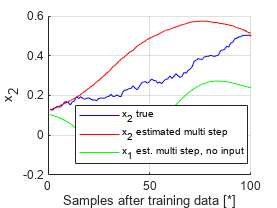


ax=gca;
exportgraphics(ax,"x1_HAVOK_with_input_multi.pdf")

clf
hold on 
plot(x2(500:1000-1,1),'blue')
plot(PredictionXsaveMulti(2,:),'red')
plot(PredictionXsaveMultiNoInput(2,:),'green')

hold off 
xlim([0 100])
grid
legend('x_2 true','x_2 estimated multi step',"x_1 est. multi step, no input",'location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')


ax=gca;
exportgraphics(ax,"x2_HAVOK_with_input_multi.pdf")
